% Parameters
fs = 1000;  % Sampling frequency (Hz)
T = 1;      % Signal duration (seconds)
N = fs * T; % Number of samples
t = (0:N-1)/fs; % Time vector

% Generate AWGN signal
noise_power = 1; % Power of noise
awgn_signal = sqrt(noise_power) * randn(1, N);
sine_signal = sqrt(2) * sin(2*pi*10*t)

sine_signal =          0    0.0888    0.1772    0.2650    0.3517    0.4370    0.5206    0.6021    0.6813    0.7578    0.8313    0.9015    0.9681    1.0309    1.0897    1.1441    1.1941    1.2393    1.2796    1.3149    1.3450    1.3698    1.3892    1.4031    1.4114    1.4142    1.4114    1.4031    1.3892    1.3698    1.3450    1.3149    1.2796    1.2393    1.1941    1.1441    1.0897    1.0309    0.9681    0.9015    0.8313    0.7578    0.6813    0.6021    0.5206    0.4370    0.3517    0.2650    0.1772    0.0888


sine_noise_signal = sine_signal + awgn_signal

sine_noise_signal =     0.3593   -1.1050   -1.4166   -0.1361    0.7369   -0.8268    1.6018   -0.1452    1.8705    0.0311    1.3333    0.4237    2.8196    2.3119    2.6120   -0.1366    1.1999    1.1075    2.6803    1.4956    0.2233    0.7132    0.9025    1.8185    0.8461    0.7837    0.9242    1.5165    1.3419    2.0980    2.7151    1.2242   -0.2934   -0.4281    0.1701    2.9686    1.1391    0.8307   -2.0368    1.5430    0.7690    0.9992    1.9316   -0.8235    1.9891   -1.3768   -0.1685    1.5066   -0.1965   -1.4695



% Frequency-domain representation using FFT
f = (-N/2:N/2-1) * (fs/N); % Frequency vector
AWGN_FFT = fftshift(fft(awgn_signal)/N); % FFT with shift
sine_fft = fftshift(fft(sine_signal)/N);
sine_noise_signal_fft = fftshift(fft(sine_noise_signal)/N);

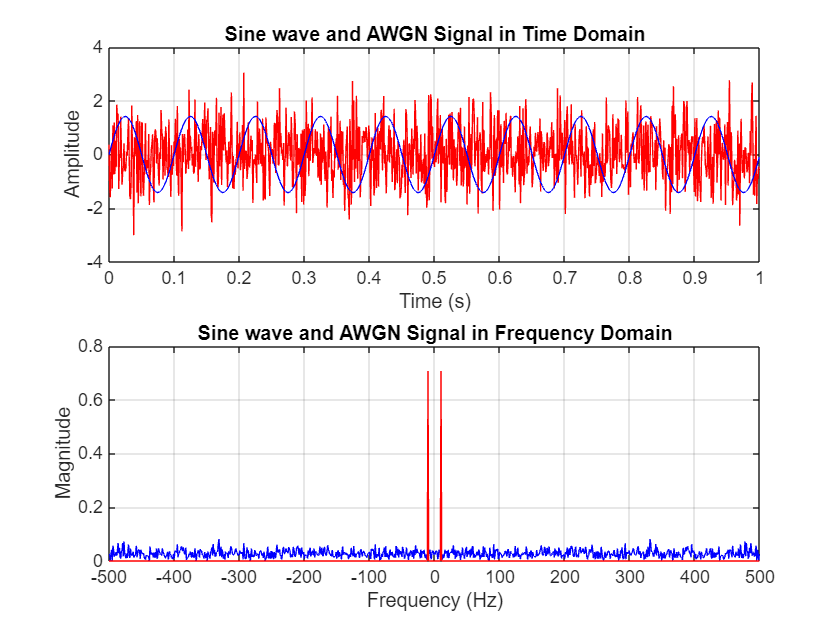

% Plot time-domain representation
figure;
subplot(2,1,1);
plot(t, awgn_signal, 'r'); hold on;
plot(t, sine_signal, 'b'); 
xlabel('Time (s)');
ylabel('Amplitude');
title('Sine wave and AWGN Signal in Time Domain');
grid on;

% Plot frequency-domain representation
subplot(2,1,2);
plot(f, abs(AWGN_FFT), 'b'); hold on;
plot(f, abs(sine_fft), 'r'); 
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Sine wave and AWGN Signal in Frequency Domain');
grid on;

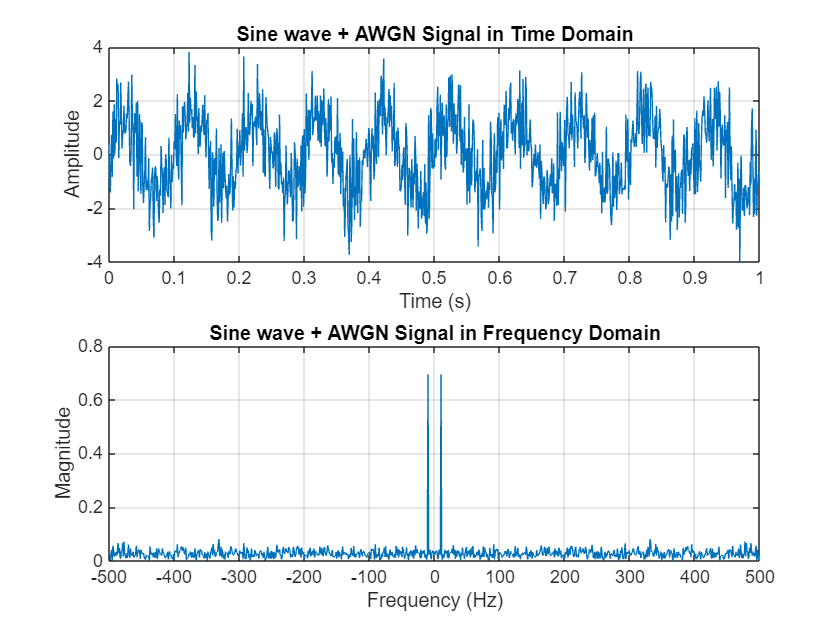

% Plot time-domain representation
figure;
subplot(2,1,1);
plot(t, sine_noise_signal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Sine wave + AWGN Signal in Time Domain');
grid on;

% Plot frequency-domain representation
subplot(2,1,2);
plot(f, abs(sine_noise_signal_fft));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Sine wave + AWGN Signal in Frequency Domain');
grid on;

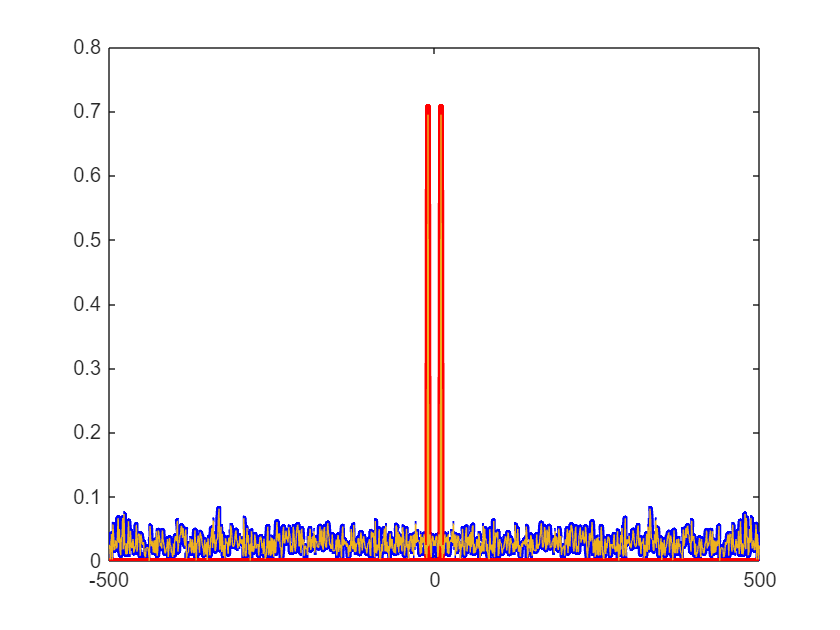

figure
plot(f, abs(AWGN_FFT), 'b', LineWidth=3); hold on;
plot(f, abs(sine_fft), 'r', LineWidth=3);  hold on;
plot(f, abs(sine_noise_signal_fft));